# JHU bootcamp 2019

# Ahrens Lab

# Analysis of whole-brain neural dynamics 

## 1. Course overview

This course aims to provide an understanding of how to analyze large-scale neural activity in behaving animals. In this experiment, zebrafish adapt their swimming patterns while the visual stimuli move forward, backward and stop. We recorded neural activity across the entire brain at single-cell resolution during this behavior.

**Figure 1: Zebrafish's swimming behavior and neural activity. Movie is available from this **[**link**](https://github.com/ahrens-lab/JHU_Bootcamp/blob/master/activity_movie.mov)

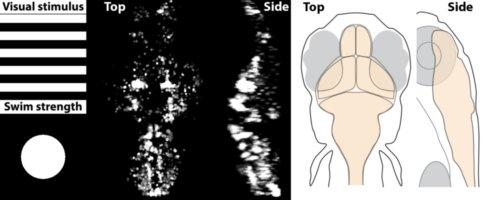

## 2. Goals

In this course, we aim to understand

**DAY 1**

**(1) Basic data handling and plotting (Sessions 1-3)**

**(2) Visualization of 3-dimensional data (Session 4)**

**DAY 2**

**(3) Correlation between neural activity and behavioral variables (Session 5)**

**(4) Low-dimensionality reduction of large-scale activity data (Session 6)**

## **3. Format**

(i) Mini lectures/discussions

(ii) Coding for basic exercise

(iii) Optional code for advanced exercise

(iv) Q&A for each sections

(v) Advanced discussion on the topics

## **4. Tutors**

Ziqiang Wei (postdoc, Ahrens lab @Janelia, weiz@janelia.hhmi.org) 

Jing Xuan Lim (grad student, Ahrens lab @Janelia, limj2@janelia.hhmi.org)

# Section 1: Load data

## 1.1 Setting up

- Please visit: [https://github.com/zqwei/explore-imaging-data.git](https://github.com/zqwei/explore-imaging-data.git)

- Download repository to your PC

- Open Matlab Live script file: JHUworkshop_Ahrenslab_2019.mlx

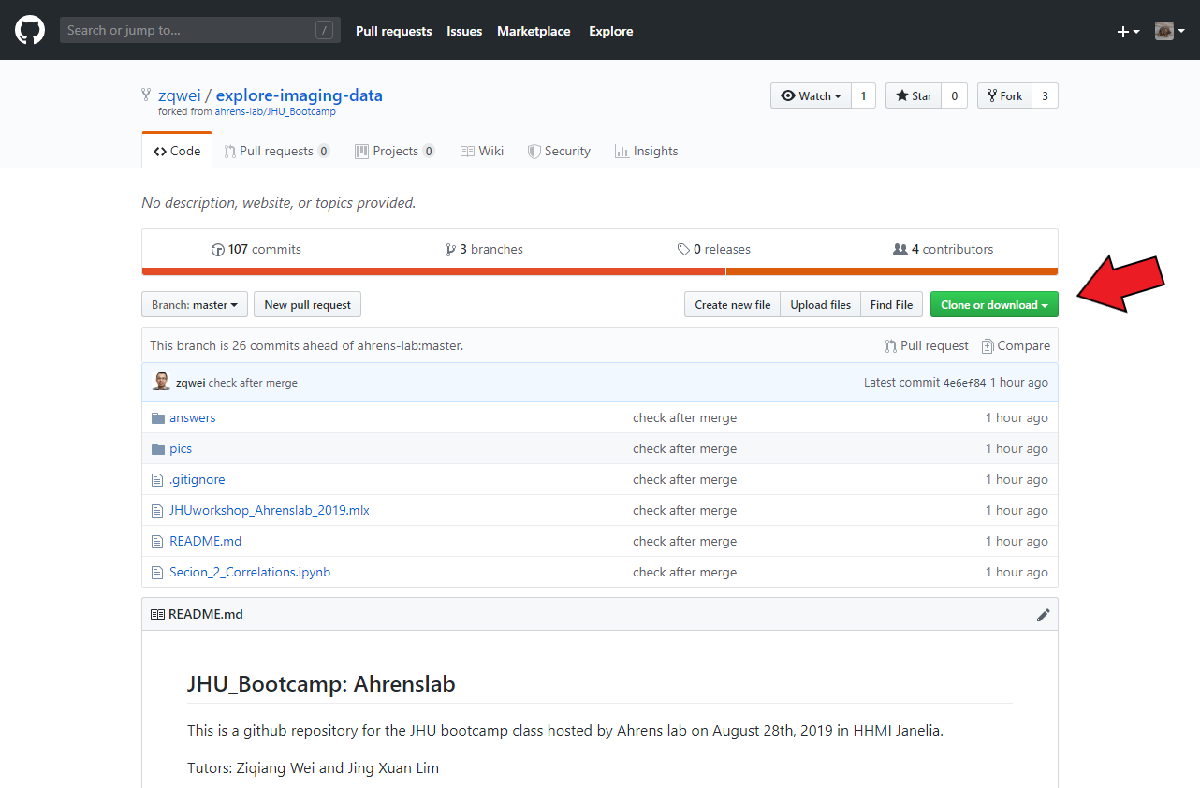

## 1.2 Download the data

Please download the data: [https://figshare.com/s/1f7c6c7565e2cf4ae705](https://figshare.com/s/1f7c6c7565e2cf4ae705). 

## 1.3 Load data

clear variables; close all; %% clear all variables & close all windows

% set Data folder location
root_dir='../Data/';

load([root_dir,'behavioral_variables.mat']);
load([root_dir,'selected_neural_data.mat']);
load([root_dir,'colortable.mat']);

% Getting the dimension of the volume
dim=size(Volume);  

% Getting the number of cells
cellnum=size(neural_response_matrix,1);

% Getting the number of timepoints
T_max=size(neural_response_matrix,2);


# Section 2: Explore data structure

Data is acquired at 1Hz for 20 minutes (i.e. 1200 time points)

## 2.1 Behavioral and stimulus data structure

`swim_power`: Fish motor signal

`visual_forward`: Command velocity of forward-moving gratings

`visual_backward`: Command velocity of backward-moving gratings

### Plot behavioral variables

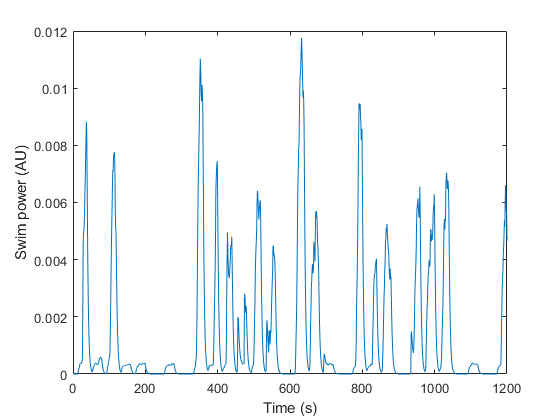

% Plot swim power
figure; plot(swim_power)
xlabel('Time (s)')
ylabel('Swim power')

### Exercise 2A: Plot stimulus variables

- Plot forward visual stimuli

- Plot backward visual stimuli

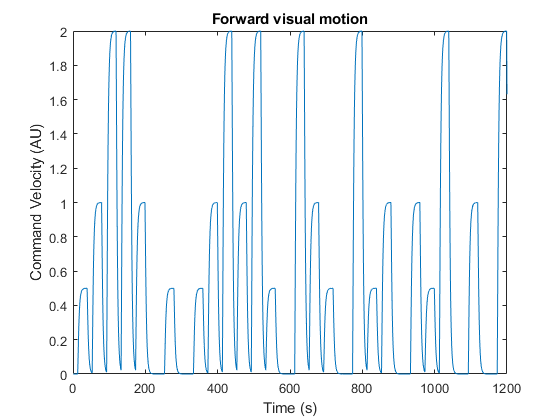

% Plot forward visual stimuli
figure; plot(forward_stimuli);
xlabel('Time (s)');
ylabel('Command Velocity');
title('Forward visual motion');

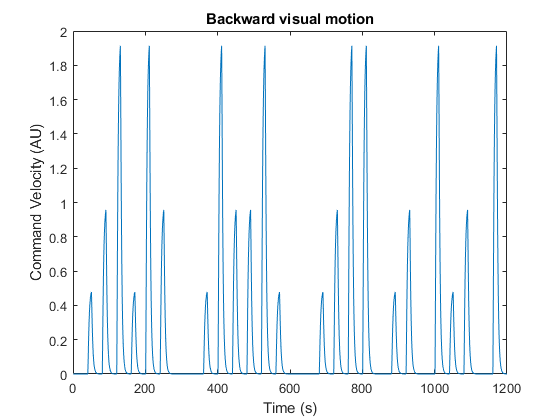


% Plot backward visual stimuli
figure; plot(backward_stimuli);
xlabel('Time (s)');
ylabel('Command Velocity');
title('Backward visual motion');

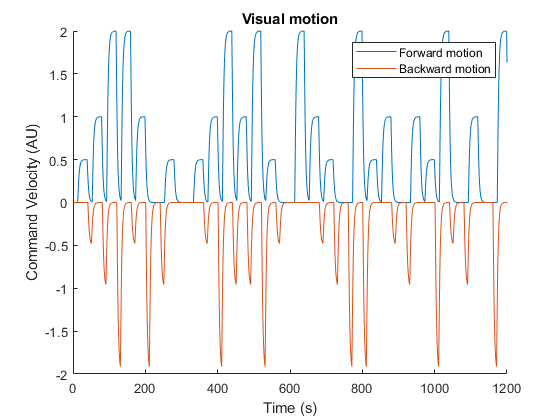

figure; hold on;
plot(forward_stimuli)
plot(-backward_stimuli)
xlabel('Time (s)')
ylabel('Command Velocity')
title('Visual motion')
legend('Forward motion','Backward motion')
hold off;

## 2.2 Neural data structure

`neural_response_matrix: `2D matrix (neuron x time) -- 1200 time points

`neural_position_XYZ: `2D matrix (neuron x location) -- 293 pixles per neuron

`Volume`: 3D volume, averaged across time (x,y,z)

### Plot neural activity

- Plot the neural activity of cell #1 to #10

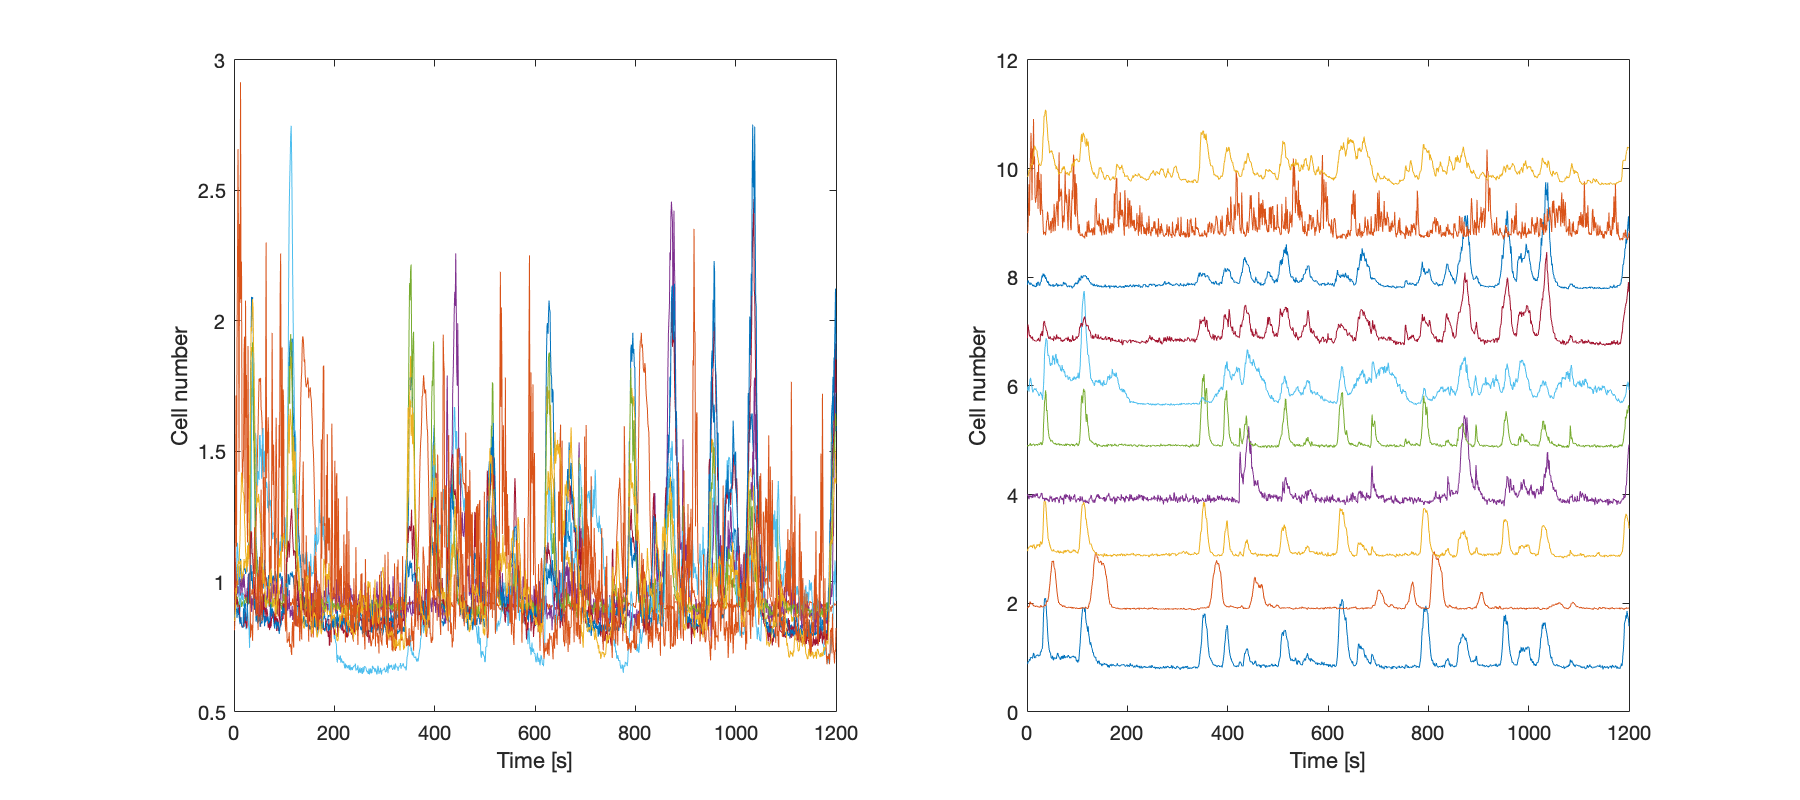

figure('Renderer', 'painters', 'Position', [0 0 900 400]);
subplot(1,2,1)
plot(neural_response_matrix(1:10,:)');
xlabel('Time [s]')
ylabel('Cell number')
subplot(1,2,2)
plot(neural_response_matrix(1:10,:)' + (0:9));
xlabel('Time [s]')
ylabel('Cell number')

### Exercise 2B

- Plot activity of next 10 cells

- Make a **function** that plots the activity of any set of cells. Do that by refractoring your previous code.

- Plot activity of every 100th cell

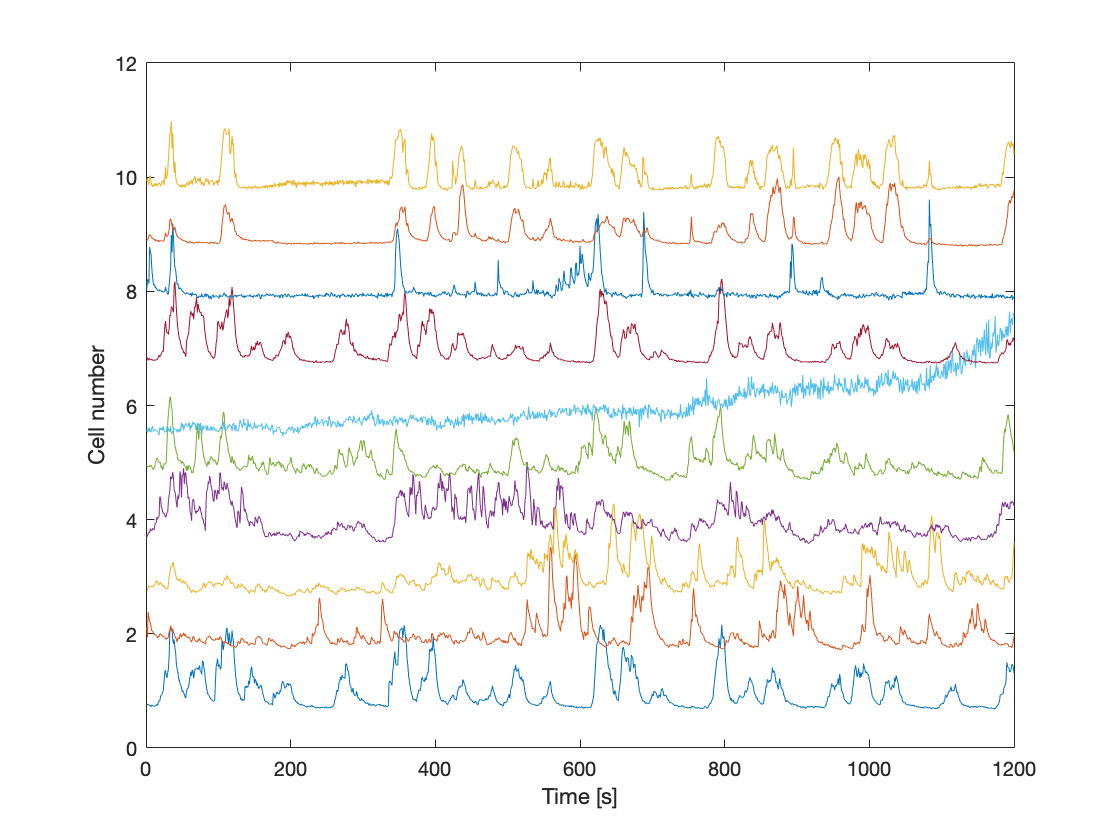

% Plot activity of next 10 cells
figure;
plot(neural_response_matrix(11:20,:)' + (0:9));
xlabel('Time [s]')
ylabel('Cell number')

#### Make a function for common plotting

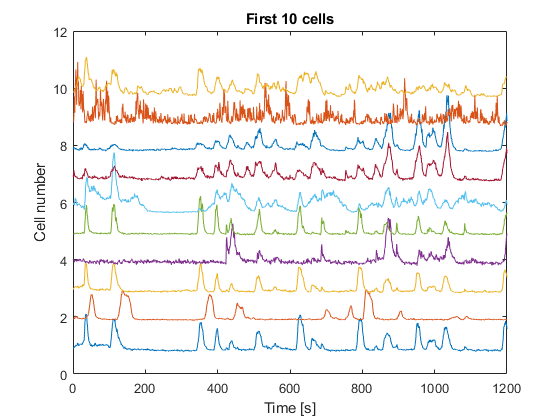

plot_cells(1:10,neural_response_matrix,'First 10 cells')

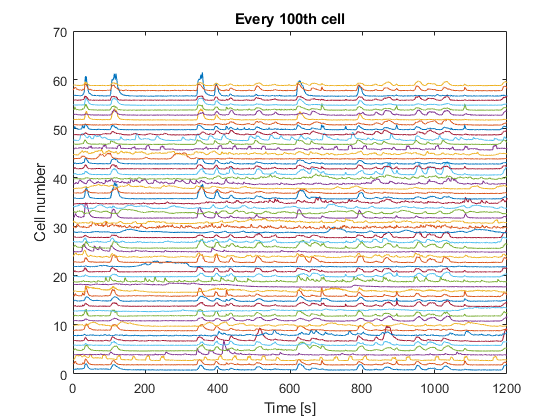

% Plot activity of every 100th cell
% Matlab expression of sequences
plot_cells(1:100:cellnum,neural_response_matrix, ...
    'Every 100th cell')

# Section 3: Peristimulus time histogram

- With respect to behavior: "swim-triggered"

- With respect to stimulus: "stimulus-triggered"

### An interesting cell: #2415

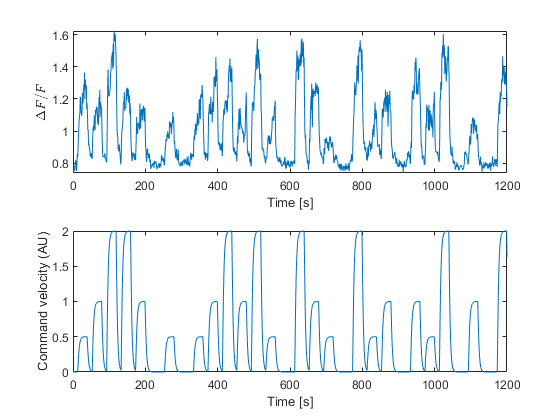

cell_trace = neural_response_matrix(2415, :);

figure;

% plot cell activity
subplot(2,1,1)
plot(cell_trace)
ylabel('$\Delta{}F/F$','Interpreter','latex')
xlabel('Time [s]')

% plot forward grating
subplot(2,1,2)
plot(forward_stimuli)
ylabel('Command velocity (AU)')
xlabel('Time [s]')

% clean up forward stimuli trace
forward_stimuli_clean = forward_stimuli;

forward_stimuli_clean =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0922    0.1910    0.2734    0.3363    0.3826    0.4161    0.4402    0.4574    0.4697    0.4784    0.4846    0.4891    0.4922    0.4945    0.4961    0.4972    0.4980    0.4986    0.4990    0.4993    0.4995    0.4996    0.4997    0.4998    0.4999    0.4999    0.4077    0.3089    0.2266    0.1637    0.1174    0.0838    0.0598    0.0426    0.0303    0.0216    0.0154


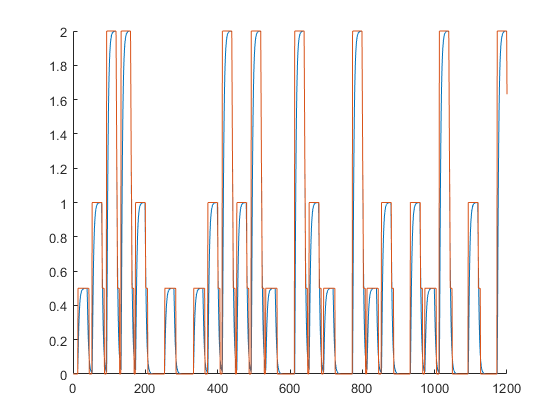

forward_stimuli_clean(forward_stimuli_clean < 0.1) = 0;
forward_stimuli_clean(forward_stimuli_clean > 0.1 & forward_stimuli_clean < 0.7) = 0.5;
forward_stimuli_clean(forward_stimuli_clean > 0.7 & forward_stimuli_clean < 1.2) = 1;
forward_stimuli_clean(forward_stimuli_clean > 1.7 & forward_stimuli_clean < 2.2) = 2;

% clean onsets
onset_indices = find(find_change(forward_stimuli_clean,0));
for onset = onset_indices
    forward_stimuli_clean(onset:onset+10) = forward_stimuli_clean(onset+10);
end

figure; hold on
plot(forward_stimuli)
plot(forward_stimuli_clean)
hold off

### Exercise 3A

Compute the stimulus-triggered average of an example neuron #2415

- Find out where are the stimuli presented. How many times was the stimulus presented?

- What is the neural activity of neuron #2415 during the period when the stimulus is presented?

- Find the triggered-average.

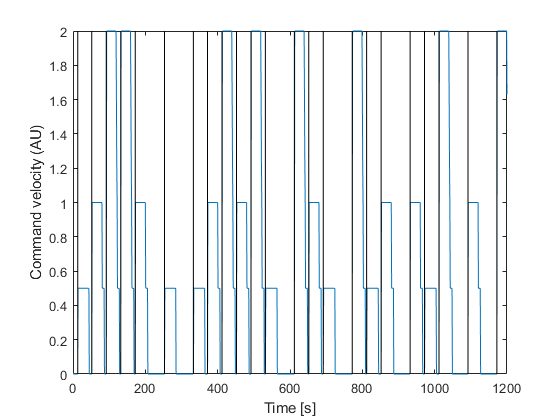

% Find the stimulus-onset timing
t = forward_stimuli_clean(1:end-1) == 0;
t_plus_1 = forward_stimuli_clean(2:end) > 0;

stim_onset = t .* t_plus_1;

figure;
plot(forward_stimuli_clean)
ylabel('Command velocity (AU)')
xlabel('Time [s]')

for onset_t = find(stim_onset)
    vline(onset_t,'k')
end


stim_onset_indices = find(stim_onset);

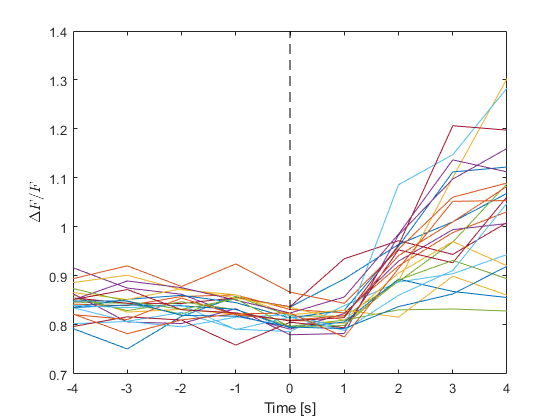

% Pull out single trials
t_around = 4;
t_axis = -t_around:t_around;

trig_indices = stim_onset_indices' + ...
               repmat(t_axis, length(stim_onset_indices), 1);

trig = cell_trace(trig_indices);

figure;
plot(t_axis, trig')
vline(0, 'k--')
ylabel('$\Delta{}F/F$','Interpreter','latex')
xlabel('Time [s]')

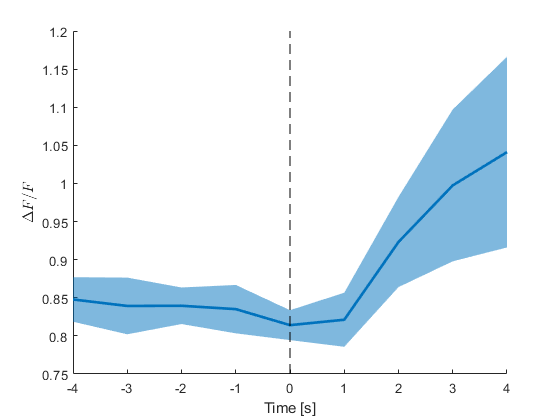

% Find the triggered-average

trig_avg = squeeze(mean(trig,1));
trig_std = squeeze(std(trig,1));

figure; hold on;
fill([t_axis,fliplr(t_axis)],[trig_avg+trig_std,fliplr(trig_avg-trig_std)],...
    [0, 0.4470, 0.7410], 'LineStyle', 'none')
alpha 0.5
plot(t_axis,trig_avg,'Color',[0, 0.4470, 0.7410],'LineWidth',2)
vline(0, 'k--')
ylabel('$\Delta{}F/F$','Interpreter','latex')
xlabel('Time [s]')

### Exercise 3B

Is there a better way to describe this triggered-average?

% Check that that is no stimulus during the "baseline"
t_axis_nostim = -t_around:0;
trig_indices_before = compute_trig_indices(stim_onset_indices,t_axis_nostim);

nostim_indices = find(forward_stimuli_clean == 0);

nostim_trials = all(ismember(trig_indices_before, nostim_indices),2);

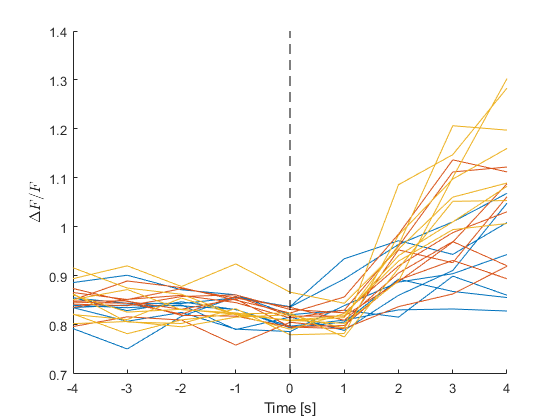

% Stimulus is at different velocities
low_onset = find_onset(forward_stimuli_clean,0,0.5);
med_onset = find_onset(forward_stimuli_clean,0,1);
high_onset = find_onset(forward_stimuli_clean,0,2);

low_trig_indices = compute_trig_indices(find(low_onset), t_axis);
med_trig_indices = compute_trig_indices(find(med_onset), t_axis);
high_trig_indices = compute_trig_indices(find(high_onset), t_axis);

low_trig = cell_trace(low_trig_indices);
med_trig = cell_trace(med_trig_indices);
high_trig = cell_trace(high_trig_indices);


figure; hold on
plot(t_axis, low_trig', 'Color', [0, 0.4470, 0.7410])
plot(t_axis, med_trig', 'Color', [0.8500, 0.3250, 0.0980])
plot(t_axis, high_trig', 'Color', [0.9290, 0.6940, 0.1250])
hold off
vline(0, 'k--')
ylabel('$\Delta{}F/F$','Interpreter','latex')
xlabel('Time [s]')

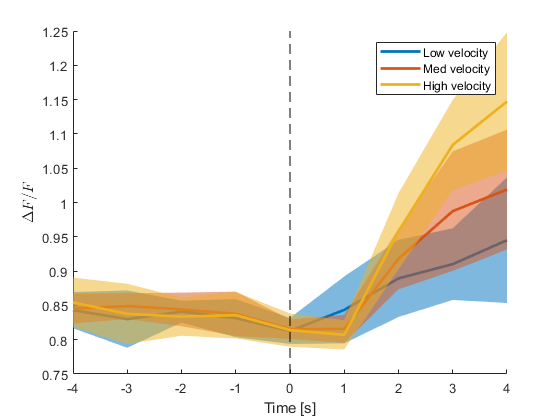


low_trig_avg = squeeze(mean(low_trig,1));
med_trig_avg = squeeze(mean(med_trig,1));
high_trig_avg = squeeze(mean(high_trig,1));

low_trig_std = squeeze(std(low_trig,1));
med_trig_std = squeeze(std(med_trig,1));
high_trig_std = squeeze(std(high_trig,1));

figure; hold on;
fill([t_axis,fliplr(t_axis)],[low_trig_avg+low_trig_std,fliplr(low_trig_avg-low_trig_std)],...
    [0, 0.4470, 0.7410], 'LineStyle', 'none')
alpha 0.5
low_mean = plot(t_axis,low_trig_avg,'Color',[0, 0.4470, 0.7410],'LineWidth',2,'DisplayName','Low velocity');

fill([t_axis,fliplr(t_axis)],[med_trig_avg+med_trig_std,fliplr(med_trig_avg-med_trig_std)],...
    [0.8500, 0.3250, 0.0980], 'LineStyle', 'none')
alpha 0.5
med_mean = plot(t_axis,med_trig_avg,'Color',[0.8500, 0.3250, 0.0980],'LineWidth',2, 'DisplayName','Med velocity');

fill([t_axis,fliplr(t_axis)],[high_trig_avg+high_trig_std,fliplr(high_trig_avg-high_trig_std)],...
    [0.9290, 0.6940, 0.1250], 'LineStyle', 'none')
alpha 0.5
high_mean = plot(t_axis,high_trig_avg,'Color',[0.9290, 0.6940, 0.1250],'LineWidth',2, 'DisplayName','High velocity');

vline(0, 'k--')
ylabel('$\Delta{}F/F$','Interpreter','latex')
xlabel('Time [s]')
legend([low_mean,med_mean,high_mean])

# Section 4: Visualization and indexing of a 3-dimensional volume

## 4.1 Projections

Multiple ways of projecting a 3D volume (XYZ) to a 2D image.

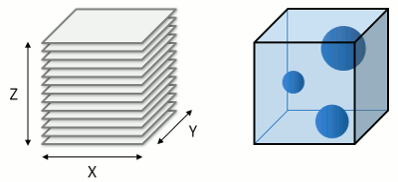

         - Maximum, Minimum, Sum, Average....

         - **Advanced discussion** -- Pros and cons for each method

### Summation projection

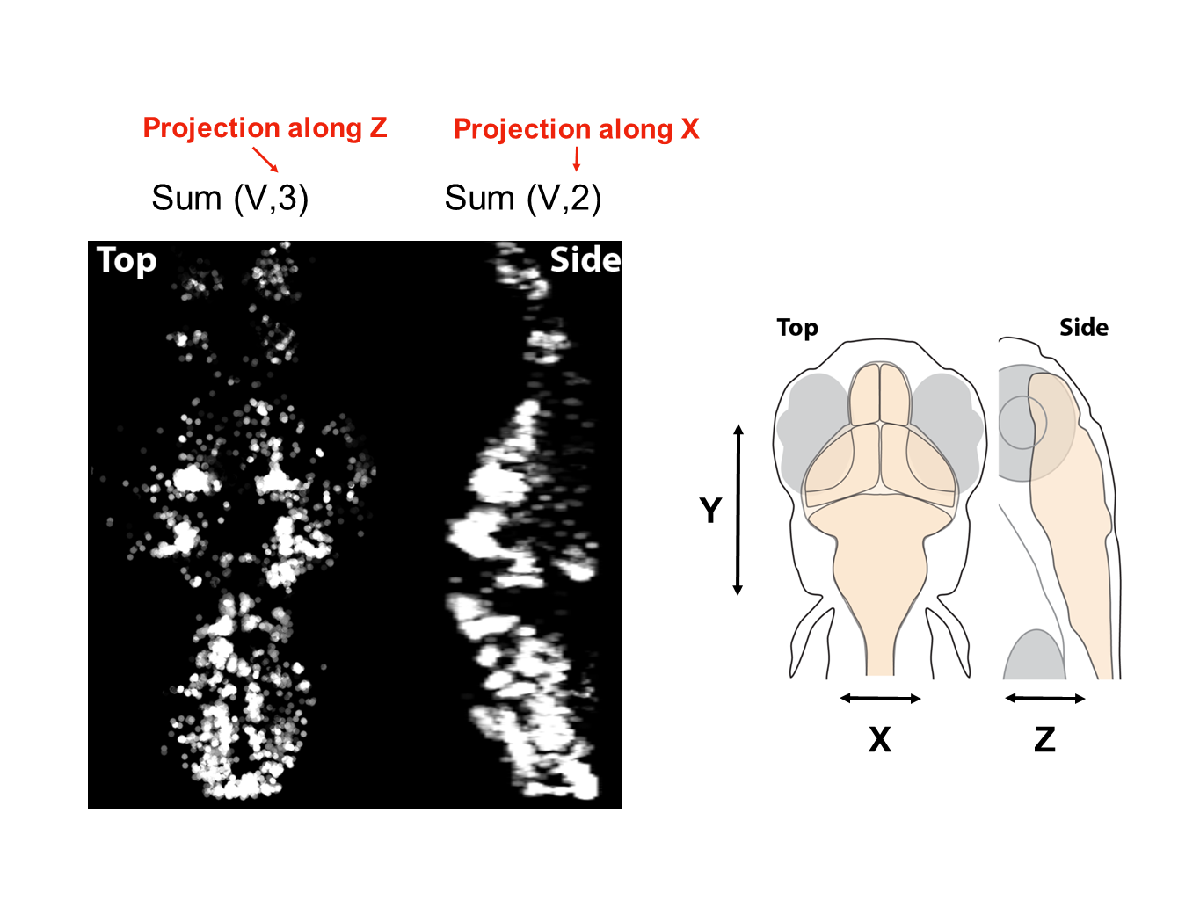

## 4.2 Indexing

Two ways of specifing a point in a 3D volume.

        - Linear index (e.g., array(i)) and subscript (e.g., array(x,y,z))

        - Pros anc cons

**Figure 2: linear index and subscript**

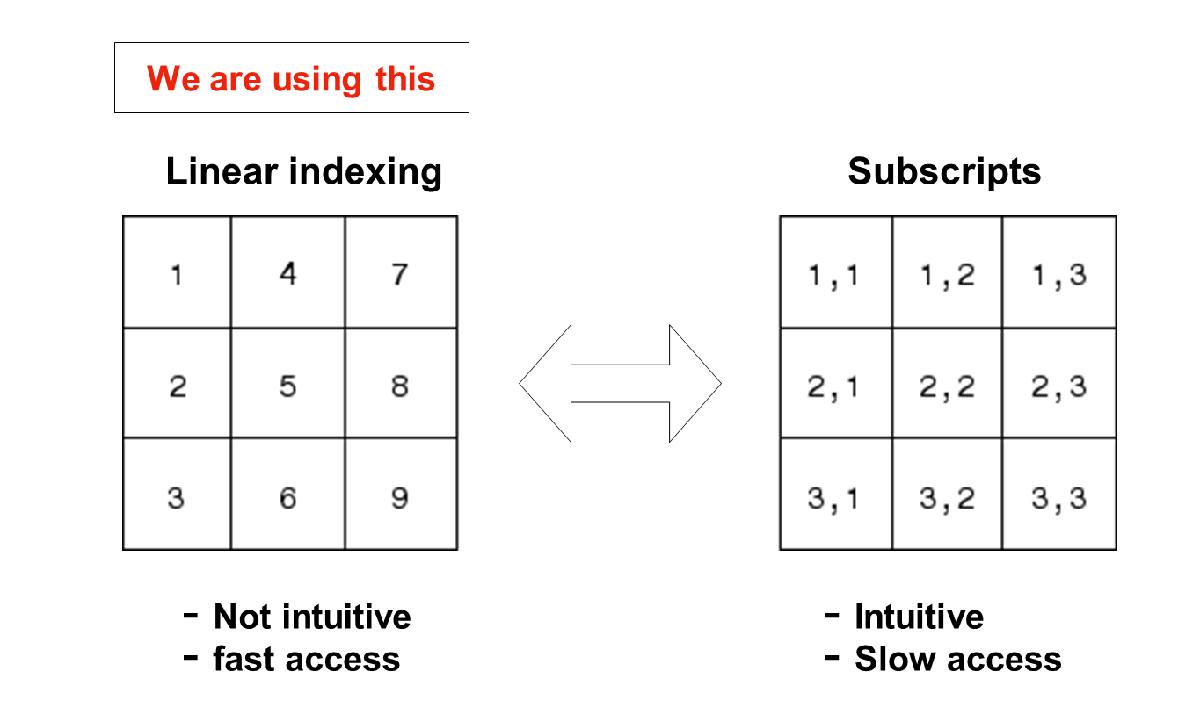

## 4.3 Visualization

### 4.3.1 Plot whole brain projections from the top and side

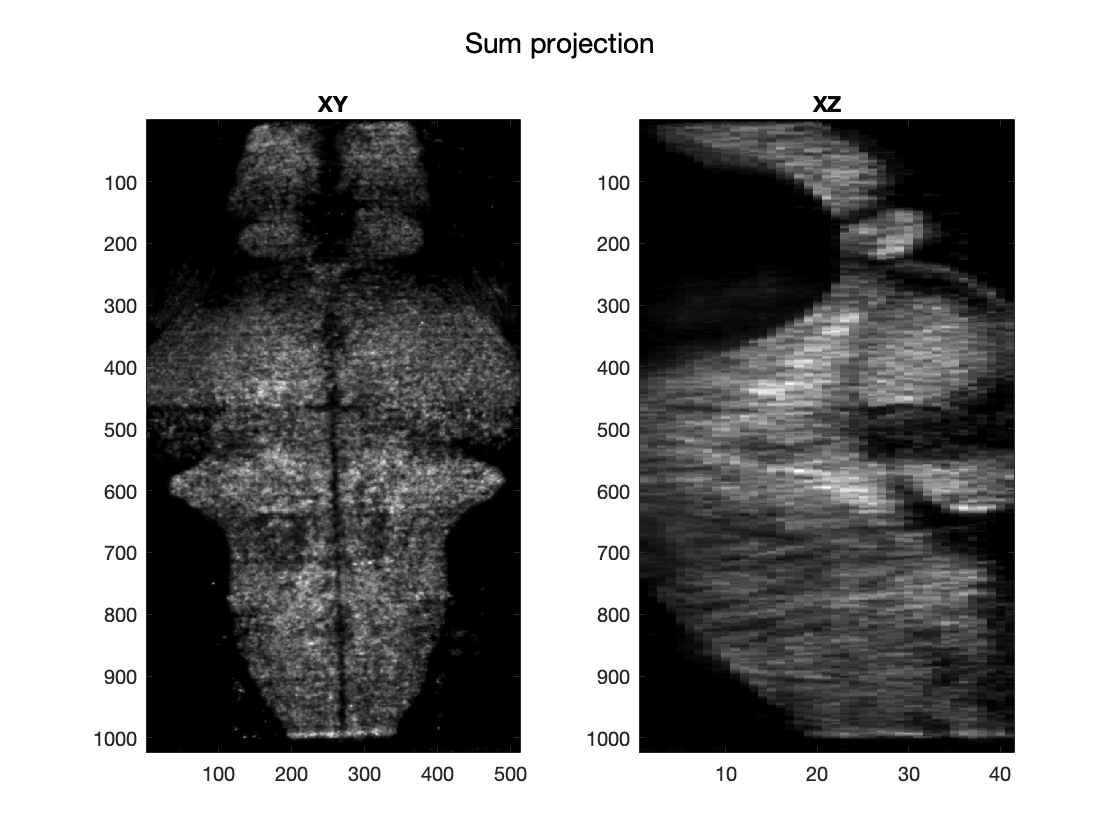

% Top projection view
Volume_XY=sum(Volume,3);
Volume_XY=squeeze(Volume_XY);

% Side projection view
Volume_XZ=sum(Volume,2);
Volume_XZ=squeeze(Volume_XZ);

% Plot side and top view
figure;
subplot(1,2,1); imagesc(Volume_XY);
title('XY'); colormap('gray');
subplot(1,2,2); imagesc(Volume_XZ);
title('XZ'); colormap('gray')
suptitle('Sum projection')

### Exercise 4A Other types of projections

Sum projections depend on how much brain vs background there is along an axis.

- Projection method -- Maximum, Minimum, Sum, Average 

- **Hint**: useful matlab functions -- **max**, **min**, **sum**, **mean** 

- * Is there a clearer way to visualize the projection? Hint: use a different cmin and cmax?

What are the pros/cons of each?

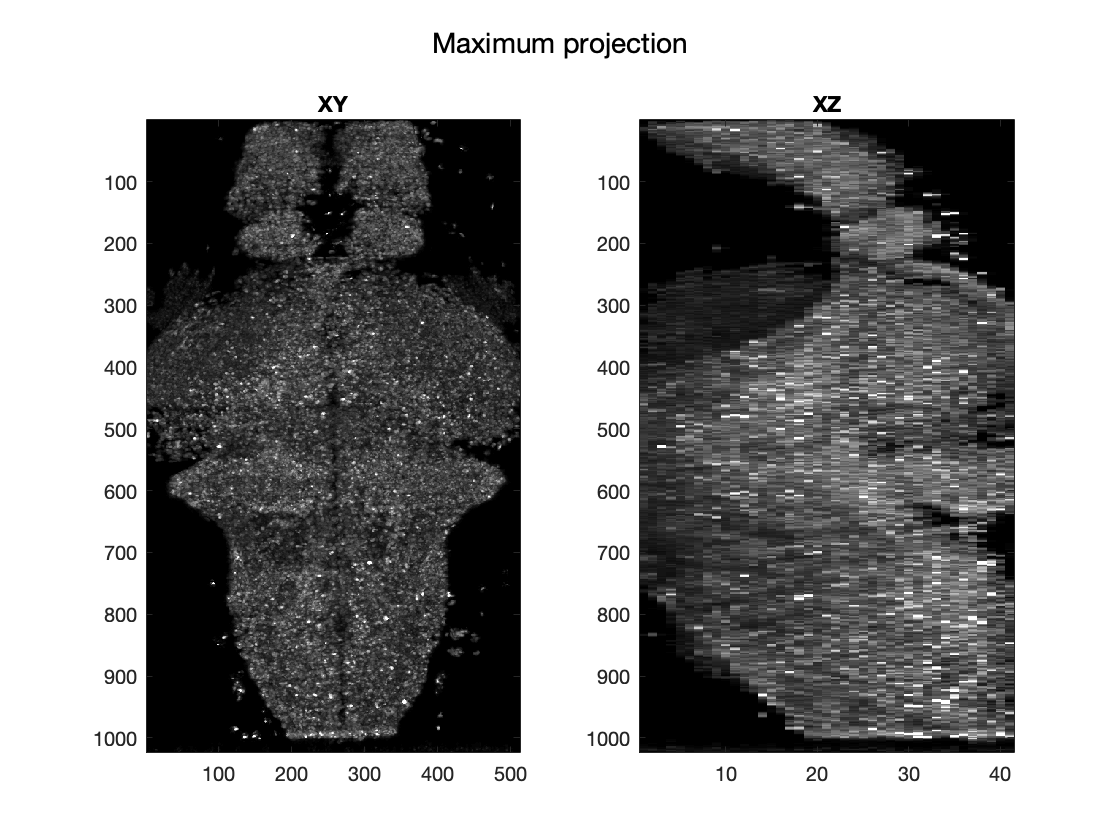

% compute and plot projections

Volume_XY_max=squeeze(max(Volume,[],3));
Volume_XZ_max=squeeze(max(Volume,[],2));
clow = prctile([Volume_XY_max(:);Volume_XZ_max(:)],0.1);
chigh = prctile([Volume_XY_max(:);Volume_XZ_max(:)],99.9);

figure;
subplot(1,2,1); imagesc(Volume_XY_max, [clow,chigh]);
title('XY'); colormap('gray');
subplot(1,2,2); imagesc(Volume_XZ_max, [clow,chigh]);
title('XZ'); colormap('gray')

suptitle('Maximum projection')

#### [Discuss] pros and cons of these projections...

### 4.3.2 Plot a single cell to its location from the top view

- Get location of cell #1 from **neural_position_XYZ** variable

- Place the cell on the top view

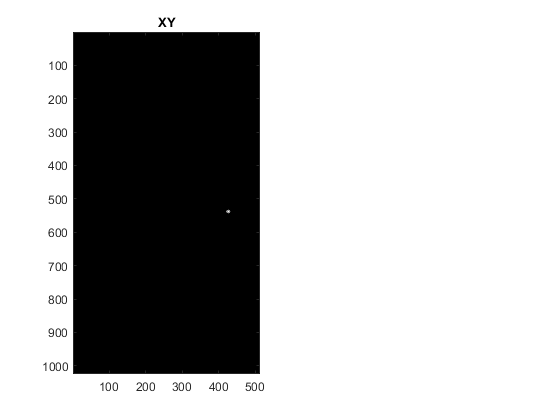

% plot location of cell #1 using linear index 
cell_map1=zeros(dim(1),dim(2),dim(3));
cell_map1(neural_position_XYZ(1,:))=1;

% Top projection view of the cell
cell_map1_XY=sum(cell_map1,3);
cell_map1_XY=squeeze(cell_map1_XY);

% Show top view
figure;
subplot(1,2,1);
imagesc(cell_map1_XY);
title('XY')
colormap('gray')

### Exercise 4B Plot a single cell to its location from the side view

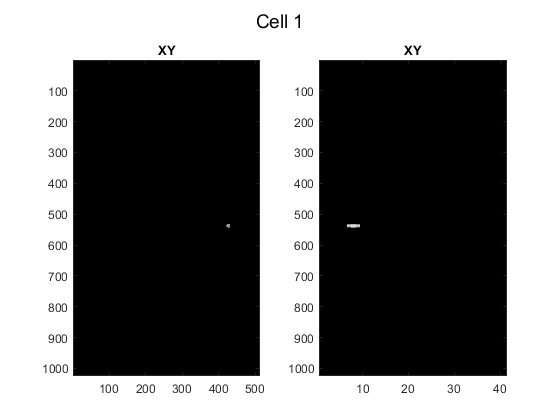

% Side projection view
cell_map1_XZ=sum(cell_map1,2);
cell_map1_XZ=squeeze(cell_map1_XZ);

% Show side view
subplot(1,2,2);
imagesc(cell_map1_XZ);
title('XY')
colormap('gray')  
suptitle('Cell 1')

### *Exercise 4C Place cell on the top view

Hints:

- Image can be presented in RGB format

- Put top view image in red channel and put cell in the green channel

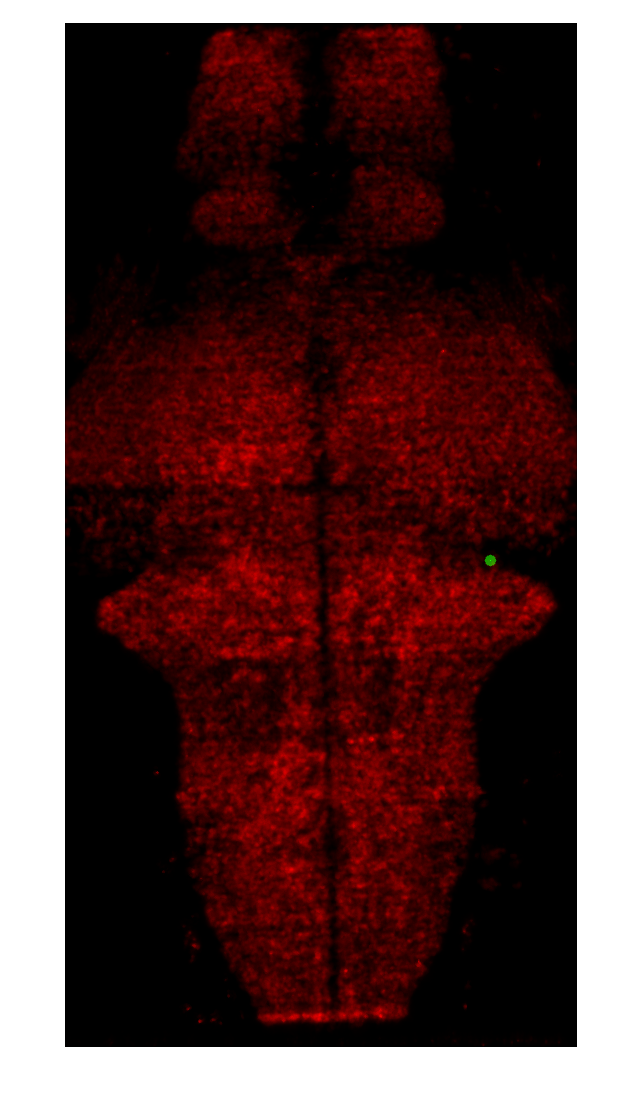

figure;
im_combine = zeros(dim(1), dim(2), 3);
im_top =  Volume_XY/max(Volume_XY(:));  % rescale to [0 1]
im_cell = cell_map1_XY/max(cell_map1_XY(:));  % rescale to [0 1]
im_combine(:, :, 1) = im_top;
im_combine(:, :, 2) = im_cell;
figure
imshow(im_combine);

### Exercise 4D Plot all cells from the top and side view

say something about for loop

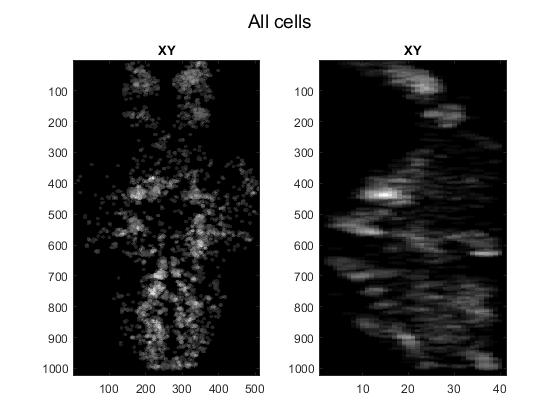

% plot locations of all cells using linear index
% use loop over neurons
cell_map2=zeros(dim(1),dim(2),dim(3));
for c =1:cellnum
    cell_map2(neural_position_XYZ(c,:))=1;
end

% Top projection view
cell_map2_XY=sum(cell_map2,3);
cell_map2_XY=squeeze(cell_map2_XY);

% Side projection view
cell_map2_XZ=sum(cell_map2,2);
cell_map2_XZ=squeeze(cell_map2_XZ);

% Show top view
figure;
subplot(1,2,1);
imagesc(cell_map2_XY);
title('XY')
colormap('gray') 

% Show side view
subplot(1,2,2);
imagesc(cell_map2_XZ);
title('XY')
colormap('gray') 
suptitle('All cells')

# Section 5: Correlation with experimental and behavioral variables

## (1) Pearson's correlation coefficient *ρ* 


$$\rho_{X,Y} =\frac{\mathrm{Cov}\left(X,Y\right)}{\sigma_X \sigma_Y }=\frac{E\left\lbrack \left(X-\mu_X \right)\left(Y-\mu_Y \right)\right\rbrack }{\sigma_X \sigma_Y }\text{ }$$


- Cov is covariance, E is expectation

- $\mu_X$, $\mu_Y$ is the mean of *X*, *Y*

- $\sigma_X$, $\sigma_Y$ is the standard deviation of *X*, *Y*

## **(2) Multiple linear regression**


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 +\ldotp \ldotp \ldotp \ldotp$$


- $X_1$, $X_2$, ... are different variables

- $\beta_0$ is constant (intercept)

- $\beta_1$, $\beta_2$,.... are regression coefficients

## (3) Pairwise correlation v.s. multiple regression

        - Difference between the two

        - Meaning of Z-scoring

        - Pros anc cons

## 5.1 Z-score variables

### Z-score behavior

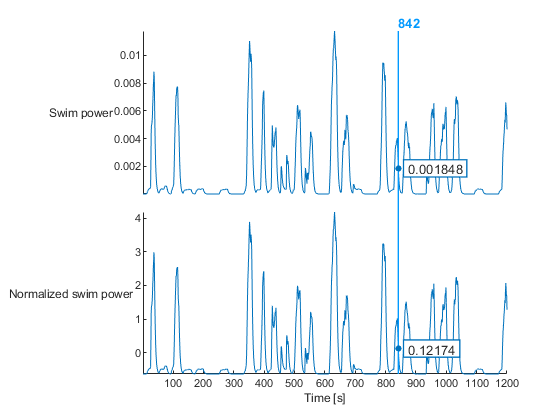

s =   StackedLineChart with properties:

            XData: [1×1200 double]
            YData: [1200×2 double]
    DisplayLabels: {2×1 cell}
            Color: [0 0.4470 0.7410]
        LineStyle: '-'
        LineWidth: 0.5000
           Marker: 'none'
       MarkerSize: 6

  Show all properties


% Z-score the swim power
swim_power_norm=zscore(swim_power);

figure;
s = stackedplot([swim_power; swim_power_norm]');
xlabel('Time [s]')
s.DisplayLabels = {'Swim power', 'Normalized swim power'}

### Exercise 5A Z-score stimuli and neural responses 

% Z-score the forward stimuli (Exercise)
visual_forward_norm=zscore(forward_stimuli);

% Z-score the backward stimuli (Exercise)
visual_backward_norm=zscore(backward_stimuli);

% Z-score the neural response
neural_response_matrix_norm=zscore(neural_response_matrix,[],2);

## 5.2 Calculate correlations

### Correlations between swim power and neural responses

- Hint: **corrcoef** function

- Hint: **corr** function

% correlation_neuron_swim = zeros(cellnum,1);
% 
% for n=1:cellnum
%     coef = corrcoef(neural_response_matrix_norm(n,:),swim_power_norm);
%     correlation_neuron_swim(n)=coef(1,2);
% end

correlation_neuron_swim = corr(neural_response_matrix_norm', swim_power_norm');

### Exercise 5B Calculate correlations between forward/backward visual stimuli

% correlation_neuron_forward = zeros(cellnum,1);
% correlation_neuron_backward = zeros(cellnum,1);

% Calculate correlations between forward/backward visual stimuli (Exercise)
correlation_neuron_forward = corr(neural_response_matrix_norm', visual_forward_norm');
correlation_neuron_backward = corr(neural_response_matrix_norm', visual_backward_norm');

## 5.3 Create correlation map across the whole brain using blue-red colormap

#### Colormap

"blue_red"                          -> Colormap which change like blue-white-red

Mimic the code used in "Show Cell locations" above, but insert correlation values instead of 1.

### Exercise 5C Visualize correlation coefficient in space for swimming

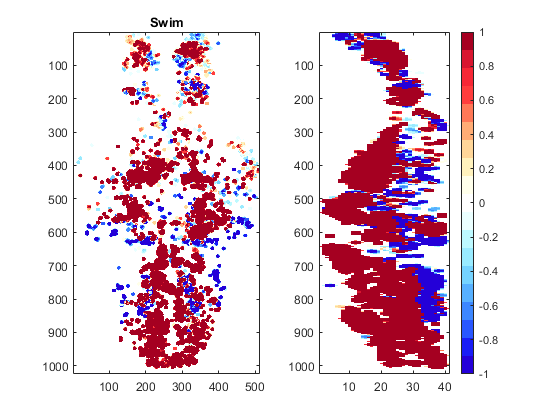

cell_map1=zeros(dim(1),dim(2),dim(3)); 
for c=1:cellnum
    cell_map1(neural_position_XYZ(c,:))=correlation_neuron_swim(c);
end

% Top projection view
cell_map_XY1=sum(cell_map1,3);
cell_map_XY1=squeeze(cell_map_XY1);

% Side projection view
cell_map_XZ1=sum(cell_map1,2);
cell_map_XZ1=squeeze(cell_map_XZ1);

% Show top and side views
figure;
subplot(1,2,1);imagesc(cell_map_XY1,[-1 1]);
title('Swim')
subplot(1,2,2);imagesc(squeeze(cell_map_XZ1),[-1 1]);
colormap(blue_red);colorbar;

### Exercise 5D Visualize correlation coefficient in space for forward visual stimulus

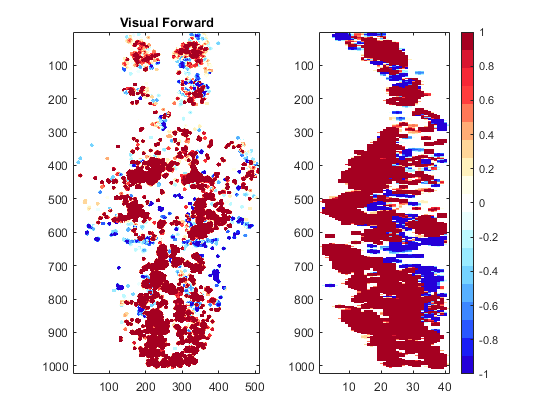

%% Show correlation map to forward stimuli
cell_map2=zeros(dim(1),dim(2),dim(3),'single');
for c=1:cellnum
    cell_map2(neural_position_XYZ(c,:))=correlation_neuron_forward(c);
end


% Top projection view
cell_map_XY2=sum(cell_map2,3);
cell_map_XY2=squeeze(cell_map_XY2);

% Side projection view
cell_map_XZ2=sum(cell_map2,2);
cell_map_XZ2=squeeze(cell_map_XZ2);

% Show top and side views
figure;
subplot(1,2,1);
imagesc(cell_map_XY2,[-1 1]);
title('Visual Forward')

subplot(1,2,2);
imagesc(squeeze(cell_map_XZ2),[-1 1]);
colormap(blue_red);colorbar;

### Exercise 5E Visualize correlation coefficient in space for backward visual stimulus

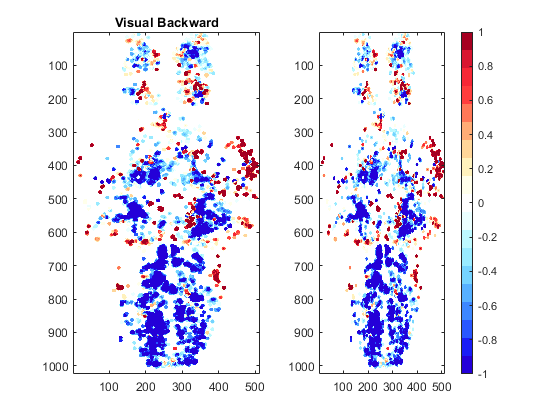

%% Show correlation map to backward stimuli  (Exercise)
cell_map3=zeros(dim(1),dim(2),dim(3),'single');
for c=1:cellnum
    cell_map3(neural_position_XYZ(c,:))=correlation_neuron_backward(c);
end

% Top projection view
cell_map_XY3=sum(cell_map3,3);
cell_map_XY3=squeeze(cell_map_XY3);

% Side projection view
cell_map_XZ3=sum(cell_map3,2);
cell_map_XZ3=squeeze(cell_map_XY3);

% Show top and side views
figure;
subplot(1,2,1);
imagesc(cell_map_XY3,[-1 1]);
title('Visual Backward')

subplot(1,2,2);
imagesc(squeeze(cell_map_XZ3),[-1 1]);
colormap(blue_red);colorbar;

## 5.6* Use multivariate regression to neural responses

- Hint: use **regress**,** mvregress** funciton

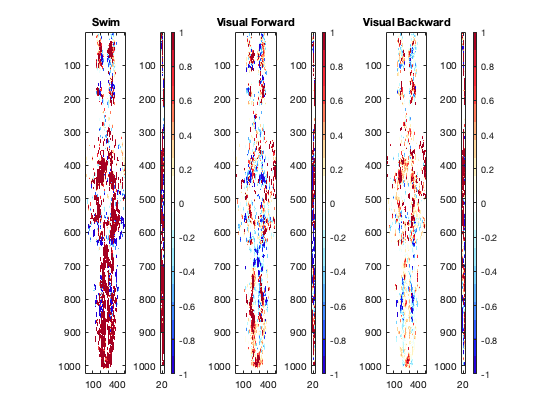

% prepare regressor vector, including intercept

regressor=[swim_power_norm; visual_forward_norm; visual_backward_norm; ones(1,1200)]';

% calculate beta for each regressor (Exercise)
betas=zeros(cellnum,4);

for c = 1:cellnum    
    betas(c,:)=regress(neural_response_matrix_norm(c,:)',regressor);   
end

% Show spatial regression map to swim power (Exercise)

cell_map4=zeros(dim(1),dim(2),dim(3),'single');
for c=1:cellnum
    cell_map4(neural_position_XYZ(c,:))=betas(c,1);
end

cell_map_XY4=sum(cell_map4,3);
cell_map_XZ4=sum(cell_map4,2);

figure;

subplot(1,6,1);imagesc(cell_map_XY4,[-1 1]);
title('Swim')
subplot(1,6,2);imagesc(squeeze(cell_map_XZ4),[-1 1]);
colormap(blue_red);colorbar;

% Show spatial regression map to forward stimuli (Exercise)

cell_map5=zeros(dim(1),dim(2),dim(3),'single');
for c=1:cellnum
    cell_map5(neural_position_XYZ(c,:))=betas(c,2);
end

cell_map_XY5=sum(cell_map5,3);
cell_map_XZ5=sum(cell_map5,2);

subplot(1,6,3);imagesc(cell_map_XY5,[-1 1]);
title('Visual Forward')
subplot(1,6,4);imagesc(squeeze(cell_map_XZ5),[-1 1]);
colormap(blue_red);colorbar;


% Show spatial regression map to backward stimuli (Exercise)

cell_map6=zeros(dim(1),dim(2),dim(3),'single');
for c=1:cellnum
    cell_map6(neural_position_XYZ(c,:))=betas(c,3);
end

cell_map_XY6=sum(cell_map6,3);
cell_map_XZ6=sum(cell_map6,2);

subplot(1,6,5);imagesc(cell_map_XY6,[-1 1]);
title('Visual Backward')
subplot(1,6,6);imagesc(squeeze(cell_map_XZ6),[-1 1]);
colormap(blue_red);colorbar;

# Section 6: Dimensionarity reduction

## (1) What is dimensionality reduction? Why necessary?

        - Difficulty of large-scale dataset

        - Difference from regression analysis

## (2) PCA v.s. NMF

        - Difference

        - Pros anc cons

        - What's suited for calcium imaging?

**Figure 3: PCA v.s. NMF of facial images**

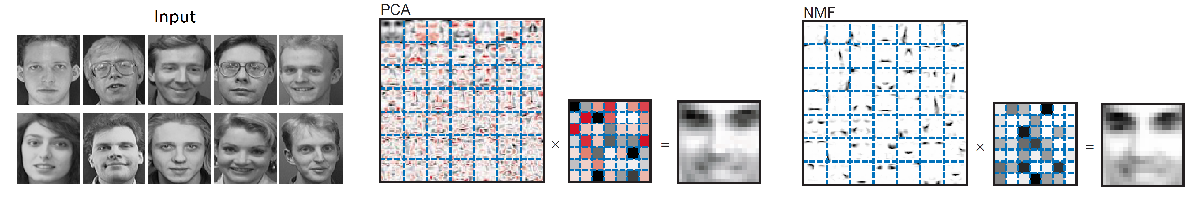

## Principal Component Analysis (PCA) and show maps for each component (Exercise)

[coeff1,comp1]=pca(neural_response_matrix_norm','NumComponents',3); % 3 PCA components

disp('PCA')

PCA


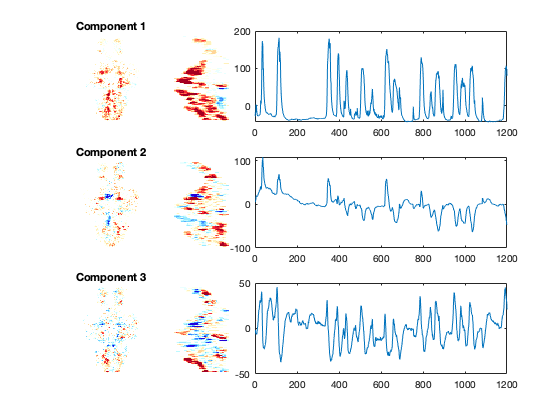

for i=1:3
    
    %% plot PCA coefficient into spatial maps (exercise)
    
    pca_map=zeros(dim(1),dim(2),dim(3));
    %% plot PCA coefficient into spatial maps (exercise)    
    for c=1:cellnum
        pca_map(neural_position_XYZ(c,:))=coeff1(c,i);
    end

    subplot(3, 5, (i-1)*5+1);

    %% top projection (exercise)
    imXY = squeeze(sum(pca_map,3));
    imagesc(imXY,[-0.25,0.25]);
    colormap(blue_red);
    axis off
    title(['Component ',num2str(i)])

    subplot(3, 5, (i-1)*5+2);

    %% side projection (exercise)
    imXZ = squeeze(sum(pca_map,2));
    imagesc(imXZ,[-1 1]);
    colormap(blue_red);
    axis off

    subplot(3, 5, (i-1)*5+[3 4 5]);

    %% plot principal component (exercise)
    plot(comp1(:,i));
    
end

## Non-Negative Matrix Factorization (NNMF) and show maps for each component

rng(3,'twister') %% initialize to a specific seed
[comp2, coeff2]=nnmf(neural_response_matrix_norm',3);

disp('NMF')

NMF


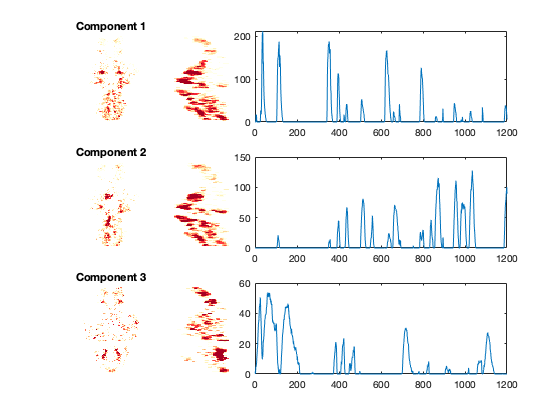


for i=1:3
    
    nmf_map=zeros(dim(1),dim(2),dim(3));
    %% plot NMF coefficient into spatial maps (exercise)

    for c=1:cellnum
        nmf_map(neural_position_XYZ(c,:))=coeff2(i,c);
    end
    
    subplot(3, 5, (i-1)*5+1);
    
    %% top projection (exercise)
    imXY=sum(nmf_map,3);
    imagesc(imXY,[-0.25,0.25]);
    colormap(blue_red);
    axis off
    title(['Component ',num2str(i)])
    
    subplot(3, 5, (i-1)*5+2);
    
    %% side projection (exercise)
    imXZ=squeeze(sum(nmf_map,2));
    imagesc(imXZ,[-1 1]);
    colormap(blue_red);
    axis off
    
    subplot(3, 5, (i-1)*5+[3 4 5]);
    
    %% plot NMF component (exercise)
    plot(comp2(:,i));

    
end